# AAE 567 HW3 Problem4

% Housekeeping commands
clear all; close all; clc;
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Define given vector
syms t
int0 = int(sin(t),0,pi);
int1 = int(t*sin(t),0,pi);
int2 = int(t^2*sin(t),0,pi);
int3 = int(t^3*sin(t),0,pi);
int4 = int(t^4*sin(t),0,pi);
int5 = int(t^5*sin(t),0,pi);
y = [int0; int1; int2; int3; int4; int5];

% The Gram Matrix
G = zeros(6);
for i = 1:6
    for j = 1:6
        G(i,j) = int(t^(j-1)*t^(i-1), 0, pi);
    end
end

% Solve for coefficients
A = G\y;
A = double(A);

% Error
fhat = dot(A, [1, t, t^2, t^3, t^4, t^5]);

$$fhat = 0.0054\,t^{5}-0.0113\,t^{4}-0.0756\,t^{3}-0.1697\,t^{2}+1.1090\,t-0.0165$$

error = int(sin(t) - fhat, 0, pi);

$$error = 4.4839e-04$$

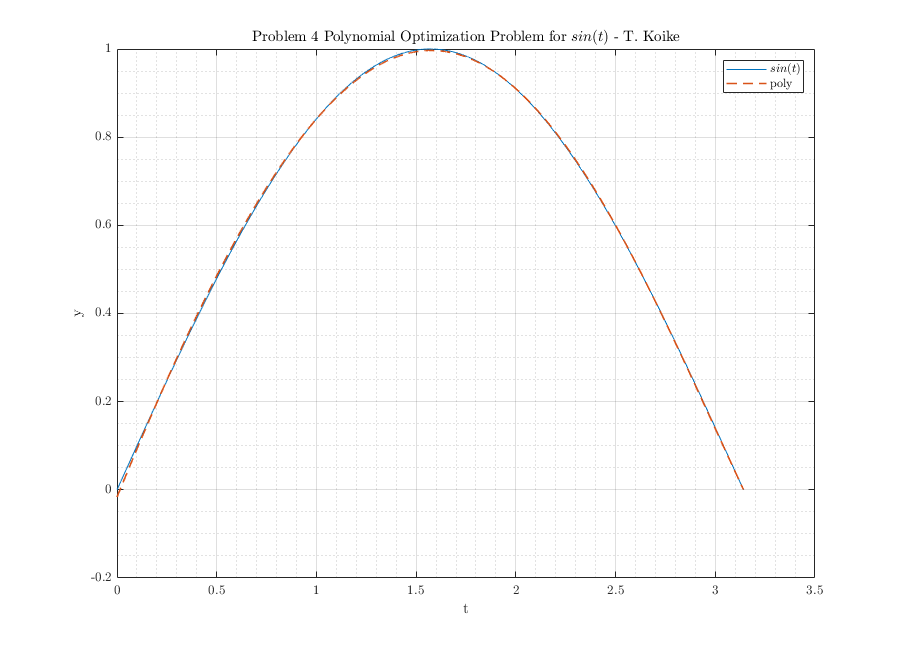


% Plotting
t = linspace(0, pi, 10000);
fig = figure("Renderer","painters", "Position",[60 60 900 650]);
    plot(t, sin(t), 'LineWidth', 0.7)
    hold on; grid on; box on; grid minor;
    plot(t, polyval(flip(A)', t), '--', "LineWidth",1.2)
    title("Problem 4 Polynomial Optimization Problem for $sin(t)$ - T. Koike")
    xlabel('t')
    ylabel('y')
    legend('$sin(t)$', 'poly')
saveas(fig,"hw3_p4_sinFitPoly.png")